# 2台のカメラによる3次元の人物姿勢推定デモ

## 1.  準備・前処理 Preparation and preprocessings

ビデオの前処理を行う。各フレームを確認し、ビデオ2については暗かったため低光量画像に対する補正処理を実施する。また、カメラ内部パラメータを参照し、歪み補正も実施する。結果として出来たフレームを使って新しいビデオを作成する。カメラの内部パラメータは、単一カメラキャリブレータ―Appで計算しておく。

Preprocess the video. Each frame is checked and video 2 is corrected for low-light images because it was dark. Also correct the distortion by referring to the camera's internal parameters. The resulting frames are then used to create a new video. The internal parameters of the camera are calculated by the Single Camera Calibrator App.

### ビデオプロパティの取得・読み込み準備 acquisition of video properties and setting for objects to load

% load video file
clear all, close all, clc;
setup_objects;

### 前処理 preprocess

doPreprocess = false;
if doPreprocess
    % 書き込み用 for writing a preprocessed frames
    vw1 = vision.VideoFileWriter(videowrite_filename1,'FileFormat','MPEG4','FrameRate',round(video_property1.FrameRate));
    i = 1;
    f = waitbar(i/frameNum1,"Calculating...");
    while ~isDone(vr1)
           frame = vr1();
           [cor_frame,newOrigin1] = undistortImage(frame,cameraParams1);
           i = i+1;
           waitbar(i/frameNum1,f);
           vw1(cor_frame);
    end
    close(f);
    release(vw1);
    
    % 書き込み用 for writing a preprocessed frames
    vw2 = vision.VideoFileWriter(videowrite_filename2,'FileFormat','MPEG4','FrameRate',round(video_property2.FrameRate));
    i = 1;
    f = waitbar(i/frameNum2,"Calculating...");
    while ~isDone(vr2)
           frame = vr2();
           frame = preprocess_for_video2Frames(frame); % 明るくする前処理
           [cor_frame,newOrigin2] = undistortImage(frame,cameraParams2);
           i = i+1;
           waitbar(i/frameNum2,f);
           vw2(cor_frame);
    end
    close(f);
    release(vw2);
    save Results/keypoints/newOrigins.mat newOrigin1 newOrigin2
else
    load Results/keypoints/newOrigins.mat
end

## 2.  2台のカメラの位置関係を計測 measure the poses of two cameras

画像に映っているものを基準として、カメラの位置・向きを推定することができます。推定のためには同一平面上に存在する4点の座標が必要です。座標は画像上での座標（X,Y）と実世界上での座標（x,y,z）がそれぞれ一対一に対応してわかっている必要があります。推定のために必要となるこれらの点をコントロールポイントと呼びます。このデモでは、背景に映っているフェンスの格子点をコントロールポイントとして用います。実世界上での座標を基準としてのカメラ１の位置・向き、そして同じ座標系を基準としたカメラ２の位置・向きがわかれば、2台のカメラの相対的な位置関係を計算することができます。したがって、コントロールポイントは2台のカメラで共通している必要はありませんが、各カメラで選択したコントロールポイントの実世界上での座標は、共通の座標系である必要があります。具体的に説明していきます。

It is possible to estimate the position and orientation of the camera based on what is seen in the image. For the estimation, we need the coordinates of four points that exist on the same plane. The coordinates must be known in a one-to-one correspondence between the image coordinates (X,Y) and the real world coordinates (x,y,z). These points that are needed for estimation are called control points. In this demo, we will use the grid points of the fence in the background as control points. If we know the position and orientation of camera 1 with respect to its coordinates in the real world, and the position and orientation of camera 2 with respect to the same coordinate system, we can calculate the relative positions of the two cameras. Therefore, the control points do not have to be common to the two cameras, but the coordinates in the real world of the control points selected by each camera must be in a common coordinate system. The detailed explanation follows.

本例では、背後のフェンスがメッシュ状になっていて、交点をとりやすく適当である。画像から交点を取得する際の誤差の影響を低減するため、できるだけ大きい四角形となるような4点を取得する。実測した結果、選択したコントロールポイントの実世界上での座標は、下の図のような概念図で表される。これらの点は画像中からある程度正確に断定できる画素に対応している必要がある。

In this example, the fence behind is grid-like, which is appropriate for easy acquisition of the intersection points. In order to reduce the effect of error in obtaining the intersection points from the image, we obtain four points that are as large a rectangle as possible. As a result of the actual measurement, the coordinates of the selected control points in the real world are represented by the conceptual diagram shown in the figure below. These points should correspond to pixels that can be determined with some accuracy from the image.

背景や周囲物体に適当なオブジェクトがない場合AprilTagのようなマーカーを事前にセットすることもできる。

If there is no suitable object in the background or surrounding objects, a marker such as AprilTag can be set in advance.

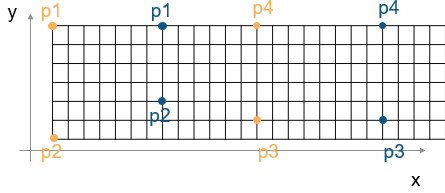　　　　　　　　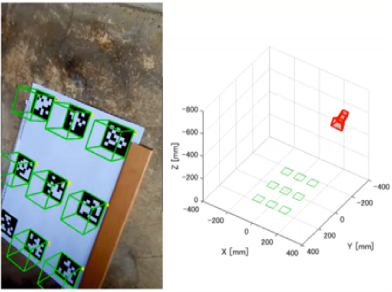

### コントロールポイントを取得する get control points

doSelectControlPts = false;
if doSelectControlPts
    % 移動体の除去のため中央値をとる take median for removal of moving objects
    vr1 = VideoReader(videowrite_filename1);
    frameCube = read(vr1);
    med_frame1 = median(frameCube,4);
    vr2 = VideoReader(videowrite_filename2);
    frameCube = read(vr2);
    med_frame2 = median(frameCube,4);
    clear frameCube;
    % 画像からのコントロールポイントの取得 get control points from imagery
    [selectedPts1,selectedPts2] = cpselect(med_frame1,med_frame2,'Wait',true);
    % 保存 save
    save Data/controlPoints/controlPoints.mat selectedPts1 selectedPts2;
else % 事前取得済みのコントロールポイントのロード load pre-selected control points
    load Data/controlPoints/controlPoints.mat
end

### カメラ位置の計算 calculation of camera pose

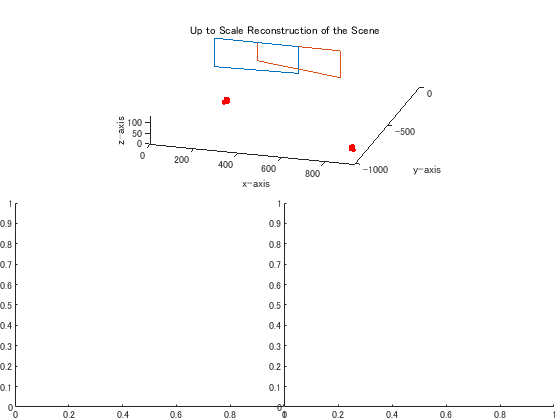

load Results/keypoints/newOrigins.mat; % 歪み補正の際の新原点　new origin coordinate of undistorted image
load Data/controlPoints/worldPts.mat; % 実測値 world coordinate of selected points
% 原点補正 origin correction
selectedPts1_offset = selectedPts1 + newOrigin1;
selectedPts2_offset = selectedPts2 + newOrigin2;

% カメラ外部パラメータ推定 estimate camera extrinsics
[r1,t1] = extrinsics(selectedPts1_offset,worldPts1,cameraParams1);
[r2,t2] = extrinsics(selectedPts2_offset,worldPts2,cameraParams2);

% 外部パラメータからカメラポーズに変換 convert extrinsics to camera pose
[ori1,loc1] = extrinsicsToCameraPose(r1,t1);
[ori2,loc2] = extrinsicsToCameraPose(r2,t2);

% 表示 visualization
figure;
tiledlayout(4,4,TileSpacing='none',Padding='none');
ax = nexttile(2,[2 2]);
ax2 = nexttile(9,[2 2]);
ax3 = nexttile(11,[2 2]);
axes(ax);
visualizeCameraPose(ax, ori1,loc1,ori2,loc2,worldPts1,worldPts2)

## 3. ディープラーニングモデルを使ってフレームごとに骨格検出 pose estimation for each frame with DL models

### 処理の確認 check the processing

#### 低光量画像の補正 low-light image correction

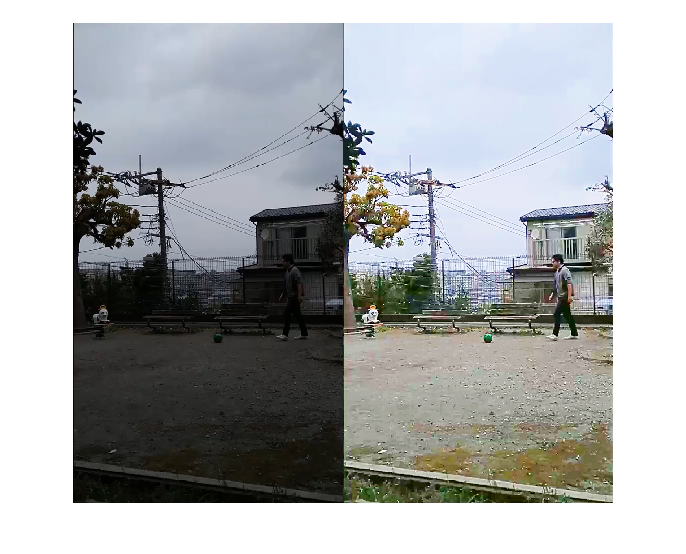

testImg = read(video_property2,1);
corImg = preprocess_for_video2Frames(testImg);
figure;imshow([testImg corImg]);

### ニューラルネットワークの読み込み load DL pretrained models

object_detectorにはYOLO v3の学習済みモデルを用いる。この機能はR2021aから、サポートパッケージとしてインストールできる。pose_detectorには、学習済みの姿勢検出モデルを用いる。詳細はReadme.mdに記載のとおりである。事前にダウンロードし、パスを通しておく。

The object_detector uses the pretrained model of YOLO v3. This feature can be installed as a support package from R2021a. For the pose_detector, we use a pretrained pose detection model. The details are described in Readme.md. Download and set the path for it in advance.

global object_detector pose_detector
object_detector = loadObjectDetector(object_detector); % 人物検出 object detection model
pose_detector = loadPoseDetector(pose_detector); % 姿勢推定 pose detection model

#### 検出のテスト test DL detection models

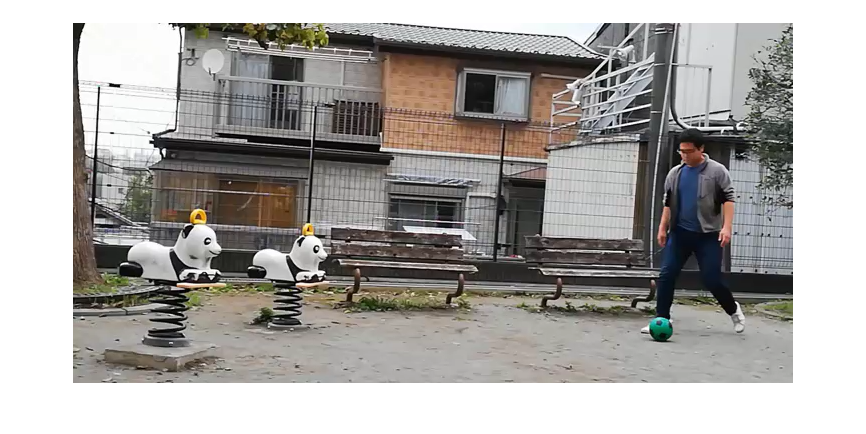

testImg = read(video_property1,1);
imshow(testImg);

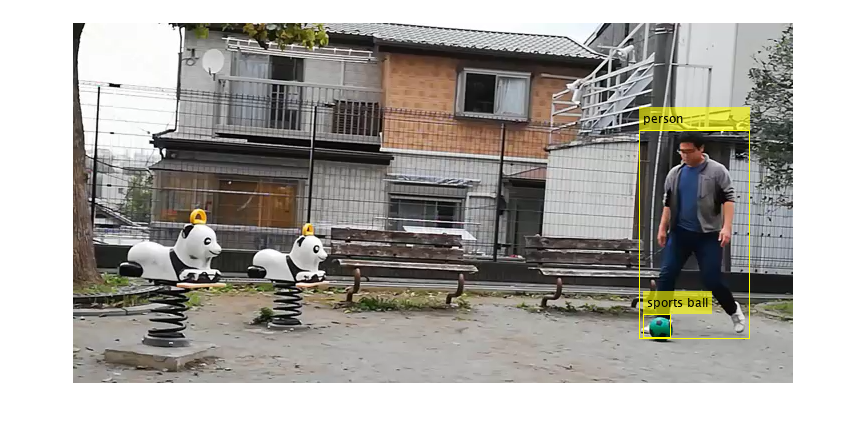

% 検出 object detection
[bbox,score,label] = object_detector.detect(testImg);
annotatedImg = insertObjectAnnotation(testImg,'rectangle',bbox,label);
imshow(annotatedImg);

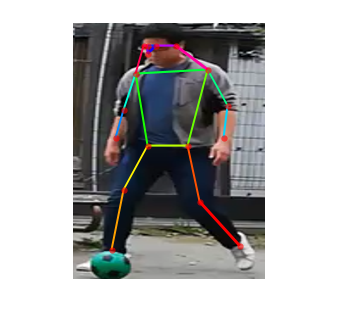

% 姿勢推定 pose detection
croppedImg = imcrop(testImg,bbox(label=='person',:));
croppedImg = imresize(croppedImg,pose_detector.InputSize(1:2));
keypoints = pose_detector.detectPose(croppedImg);
% 表示 visualization
annotatedImg = pose_detector.visualizeKeyPoints(croppedImg,keypoints);
imshow(annotatedImg);

### フレームに対する姿勢検出 pose estimation for every frame

doDetection = false;
if doDetection
    % Variable for output
    keypointsArray1 = zeros(17,3,frameNum1);

    i = 1;
    f = waitbar(i/frameNum1,"Calculating...");
    while ~isDone(vr1)
           cor_frame = vr1();
           [keypoints,isdetected] = poseDetection4Frame(cor_frame,object_detector,pose_detector);
           keypointsArray1(:,:,i) = keypoints;
           i = i+1;
           waitbar(i/frameNum1,f);
    end
    close(f);
    
    % Variable for output
    keypointsArray2 = zeros(17,3,frameNum2);

    i = 1;
    f = waitbar(i/frameNum2,"Calculating...");
    while ~isDone(vr2)
           cor_frame = vr2();
           [keypoints,isdetected] = poseDetection4Frame(cor_frame,object_detector,pose_detector);
           keypointsArray2(:,:,i) = keypoints;
           i = i+1;
           waitbar(i/frameNum2,f);
    end
    close(f);
    save Results/keypoints/detectionResults.mat keypointsArray1 keypointsArray2    
end

## 4. 検出した各関節の位置を補正 estimted pose correction with signal processing

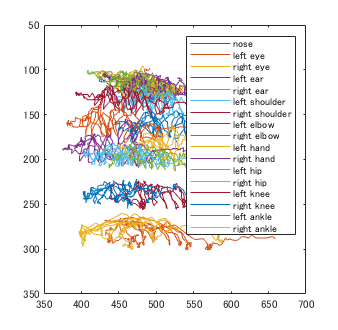

load Results/keypoints/detectionResults.mat;
labels = import_keypointsAnnotation('Data/keypointAnnotation/keypointsAnnotation_EN.txt');
plot(squeeze(keypointsArray1(:,1,:))',squeeze(keypointsArray1(:,2,:))');
axis ij
legend(labels);

ノイジーな検出結果が見られるため、ある程度平滑化して補正する。平滑化の強度を上げすぎると動きが無くなってしまうため、バランスは調整できるようにする。

Noisy detection results are observed, so we compensate for this by smoothing to some extent. If the intensity of the smoothing is increased too much, the motion will be lost, so you need to balance them. 

dataTmp = squeeze(keypointsArray1(17,2,:));

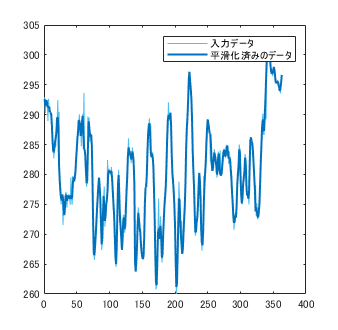

% 入力データの平滑化
smoothedData2 = smoothdata(dataTmp,"rloess",6);

% 結果の表示
clf
plot(dataTmp,"Color",[77 190 238]/255,"DisplayName","入力データ")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","平滑化済みのデータ")
hold off
legend

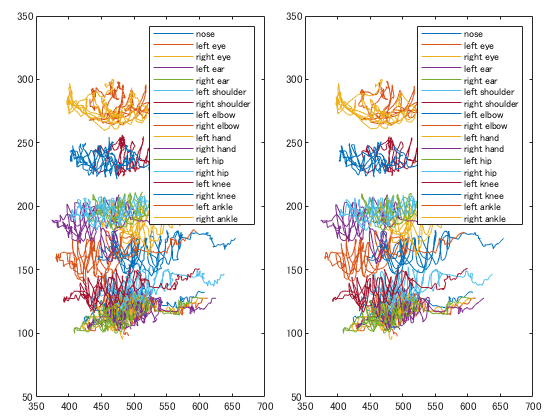

% 試行結果を適用 apply trial results
sm_keypointsArray1 = smoothdata(keypointsArray1,3,"rloess",6);
sm_keypointsArray2 = smoothdata(keypointsArray2,3,"rloess",6);
% 表示 visualization
figure; tiledlayout(1,2,'TileSpacing',"compact","Padding","compact");
nexttile;
plot(squeeze(keypointsArray1(:,1,:))',squeeze(keypointsArray1(:,2,:))')
legend(labels);
nexttile;
plot(squeeze(sm_keypointsArray1(:,1,:))',squeeze(sm_keypointsArray1(:,2,:))')
legend(labels);

## 5. ビデオの同期 synchronization of videos

### 同期に使う関節を選択 select joint used for delay estimation

特徴的な動きの関節をピックアップし、同期に用いる。今回は右手を選択する。

Pick a joint with a characteristic movement and use it for synchronization. In this case, we will select the right hand.

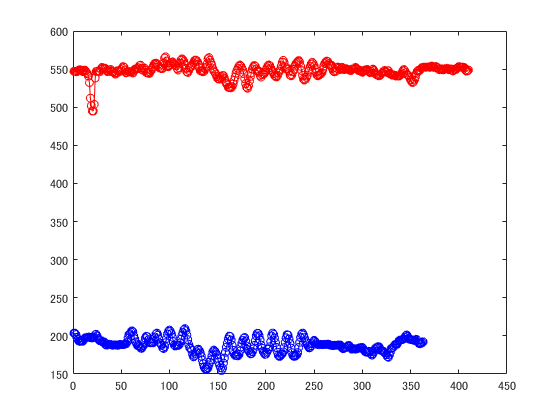

loc1 = squeeze(sm_keypointsArray1(11,2,:));
loc2 = squeeze(sm_keypointsArray2(11,2,:));
figure;
plot(loc1,'bo-');
hold on;
plot(loc2,'ro-');

### 前処理 preprocess

同期のため、finddelay関数を使う。高周波信号だけを取り出すため、ハイパスフィルタを前処理に使う。もし2つのビデオのフレームレートが異なる場合、あらかじめ内挿などで揃えておく。

Use the finddelay function for synchronization. Use a high-pass filter for preprocessing to extract only the high-frequency signals. If the frame rates of the two videos are different, interpolate in advance to align them.

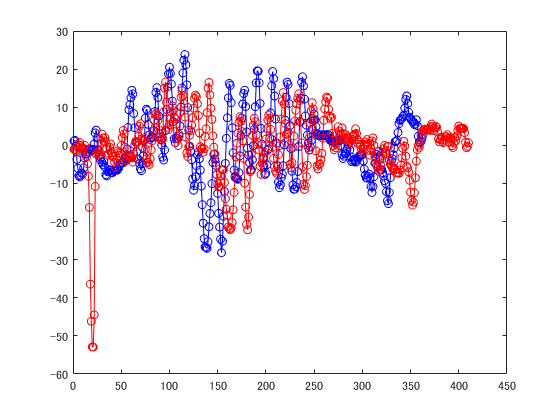

% サンプリングレートの取得　sampling rate
video_property1 = VideoReader(videowrite_filename1);
video_property2 = VideoReader(videowrite_filename2);
fs1 = video_property1.FrameRate;
fs2 = video_property2.FrameRate;
loc1_hp = highpass(loc1,0.1,fs1); % 0.1Hz以上を通す low-frequency component is removed
loc2_hp = highpass(loc2,0.1,fs2); % 0.1Hz以上を通す low-frequency component is removed
figure;
plot(loc1_hp,'bo-');
hold on;
plot(loc2_hp,'ro-');

### 時間遅れの計算 estimation of the delay

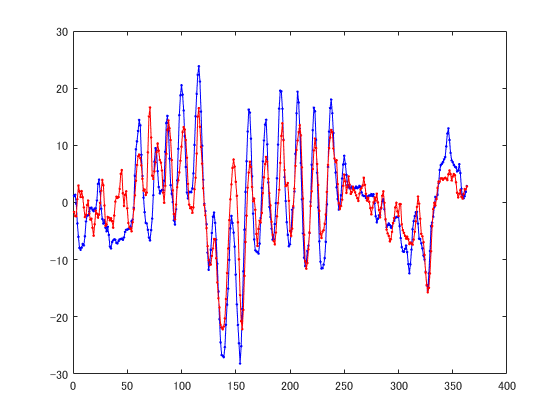

delayIdx = finddelay(loc1_hp,loc2_hp);
if delayIdx < 0
    i1 = -delayidx:length(loc1_hp);
    i2 = 1:length(loc2_hp);
elseif delayIdx > 0
    i1 = 1:length(loc1_hp);
    i2 = delayIdx:length(loc2_hp);
else
    i1 = 1:length(loc1_hp);
    i2 = 1:length(loc2_hp);
end
commonL = min(length(i1),length(i2));
i1 = i1(1:commonL); % 長さを揃える
i2 = i2(1:commonL);

figure;plot(loc1_hp(i1),'b.-');
hold on;
plot(loc2_hp(i2),'r.-');

### ビデオで確認 confirmation with video

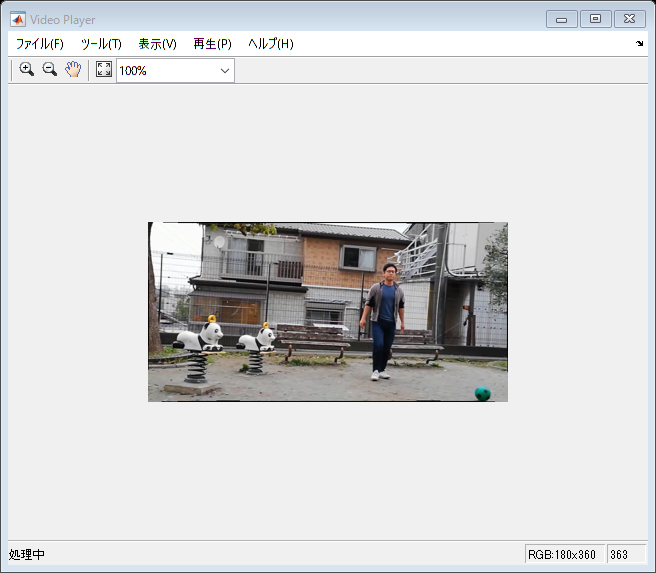

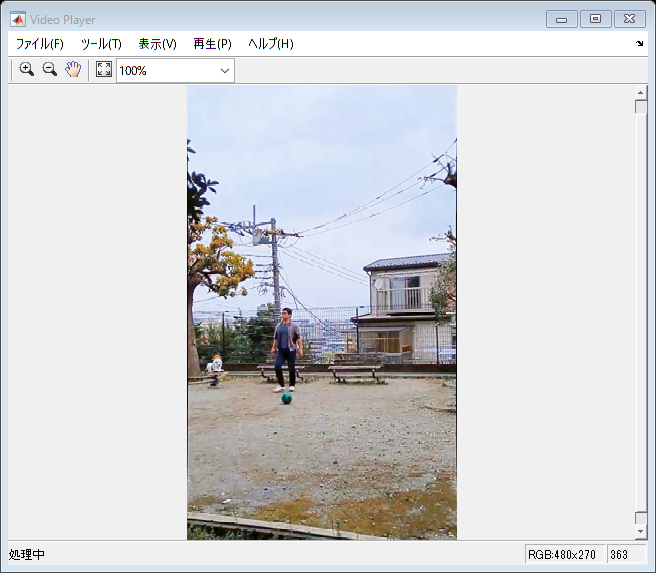

vr1 = VideoReader(videowrite_filename1);
vr2 = VideoReader(videowrite_filename2);
vp1 = vision.VideoPlayer;
vp2 = vision.VideoPlayer;
vp1.Position = [50 50 640 480]; vp2.Position = [300 50 640 480];
for i = 1:commonL
    frame1 = read(vr1,i1(i));
    frame2 = read(vr2,i2(i));
    vp1(imresize(frame1,0.5));
    vp2(imresize(frame2,0.5));
end

## 6. 各関節の3次元位置を計測 calculation of 3D pose

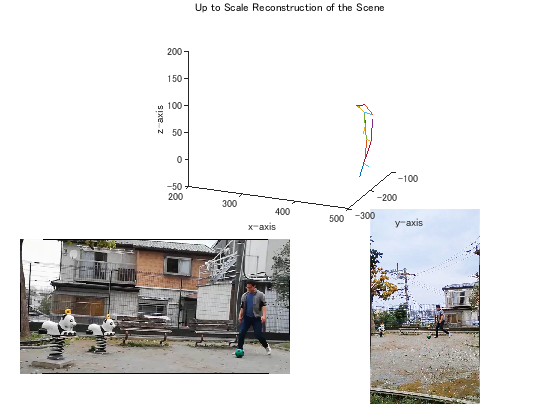

% カメラ行列 camera matrix
camMatrix1 = cameraMatrix(cameraParams1,r1,t1);
camMatrix2 = cameraMatrix(cameraParams2,r2,t2);

axis(ax,[200 500 -300 -100 -50 200]);
for idx = 1:commonL
    % 関節位置の3次元位置計算 Calculation of 3D positions for joints
    pts3D = triangulate(sm_keypointsArray1(:,1:2,i1(idx))+newOrigin1,sm_keypointsArray2(:,1:2,i2(idx))+newOrigin2,camMatrix1,camMatrix2);
    % 可視化 visualization
    visualizeJoints_and_images(pts3D,ax,ax2,ax3,pose_detector,vr1,i1,vr2,i2,idx);
    drawnow;
end

## 7. まとめ summary

このサンプルでは、2次元の姿勢推定をステレオビデオに適用することで3次元姿勢推定を行いました。各時間で3次元位置がわかれば、その先様々な解析に用いることができます。また、関節でなくてもボールの軌跡解析などにも行うことができます。注意点として2台のカメラの両方で共通して検知できている関節しか3次元計測はできません。また高精度な3次元計測のためには、2台のカメラを90度離れて設置するのが理想です。以上のことと、計測したい運動、そしてコントロールポイントを考慮して全体のレイアウトを考える必要があります。

In this sample, we applied 2D pose estimation to stereo video to get 3D pose estimation. Once the 3D position is known at each time, it can be used for various analyses. It can also be used to analyze the trajectory of a ball, even if it is not a joint. It is important to note that only joints that are commonly detected by both cameras can be measured in 3D. Also, for highly accurate 3D measurement, it is ideal to place the two cameras 90 degrees apart. You need to consider the above, the motion you want to measure, and the control points in the overall layout.

## サポート関数

function visualizeCameraPose(ax,ori1,loc1,ori2,loc2,worldPts1,worldPts2)
    ori1 = convertYZ(ori1);
    loc1 = convertYZ(loc1);
    ori2 = convertYZ(ori2);
    loc2 = convertYZ(loc2);
    worldPts1 = convertYZ([worldPts1,zeros(size(worldPts1(:,1)))]);
    worldPts2 = convertYZ([worldPts2,zeros(size(worldPts2(:,1)))]);
    
    plot3([worldPts1(:,1) worldPts2(:,1);worldPts1(1,1) worldPts2(1,1)], ...
        [worldPts1(:,2) worldPts2(:,2);worldPts1(1,2) worldPts2(1,2)], ...
        [worldPts1(:,3) worldPts2(:,3);worldPts1(1,3) worldPts2(1,3)], ...
        'MarkerSize',20);
    axis equal;
    hold(ax,'on');
    plotCamera('Size',10,'Orientation',ori1,'Location',...
         loc1);
    plotCamera('Size',10,'Orientation',ori2,'Location',...
         loc2);
    
    view([22 20]);
    % Label the axes
    xlabel('x-axis');
    ylabel('y-axis');
    zlabel('z-axis')
    
    title('Up to Scale Reconstruction of the Scene');
end

function visualizeJoints_and_images(pts3D,ax,ax2,ax3,pose_detector,vr1,i1,vr2,i2,idx)
    pts3D = convertYZ(pts3D);
    while ~strcmp(ax.Children(1).Type,'hgtransform')
        delete(ax.Children(1));
    end
    visualizeKeyPoints_in_3D(ax, pose_detector, pts3D);
    
    showFrame1 = read(vr1,i1(idx));
    imshow(showFrame1,'Parent',ax2);
    showFrame2 = read(vr2,i2(idx));
    imshow(showFrame2,'Parent',ax3);
end


Copyright 2021 The MathWorks, Inc.